# Homework 2 (Solution) 

Math 3607

Tae Eun Kim

format long g

## Problem 1 (Leap Year)

#### Solution 1

Consider the pseudocode provided in Lecture 3:

Below is a direct translation of the pseudocode:

year = 2021; % this year is not a leap year.
% or  year = input('Enter year: ');
msgCommon = 'Given year is a common year.';
msgLeap = 'Given year is a leap year.';

if mod(year, 4) ~= 0
    disp(msgCommon)
elseif mod(year, 100) ~= 0
    disp(msgLeap)
elseif mod(year, 400) ~= 0
    disp(msgCommon)
else
    disp(msgLeap)
end

Given year is a common year.


**Analysis.** The key reason why the code above work is due to the fact that branches of `if`-statement are visited sequentially from top to bottom and only the first branch whose condition evaluates to "true" is executed. One of the best ways to leverage this mechanism is to gradually narrow down the scope of the conditions if possible. See the venn diagram below which schematically partitions all years into common years (light green) and leap years (light red) according to their numerical characterization.

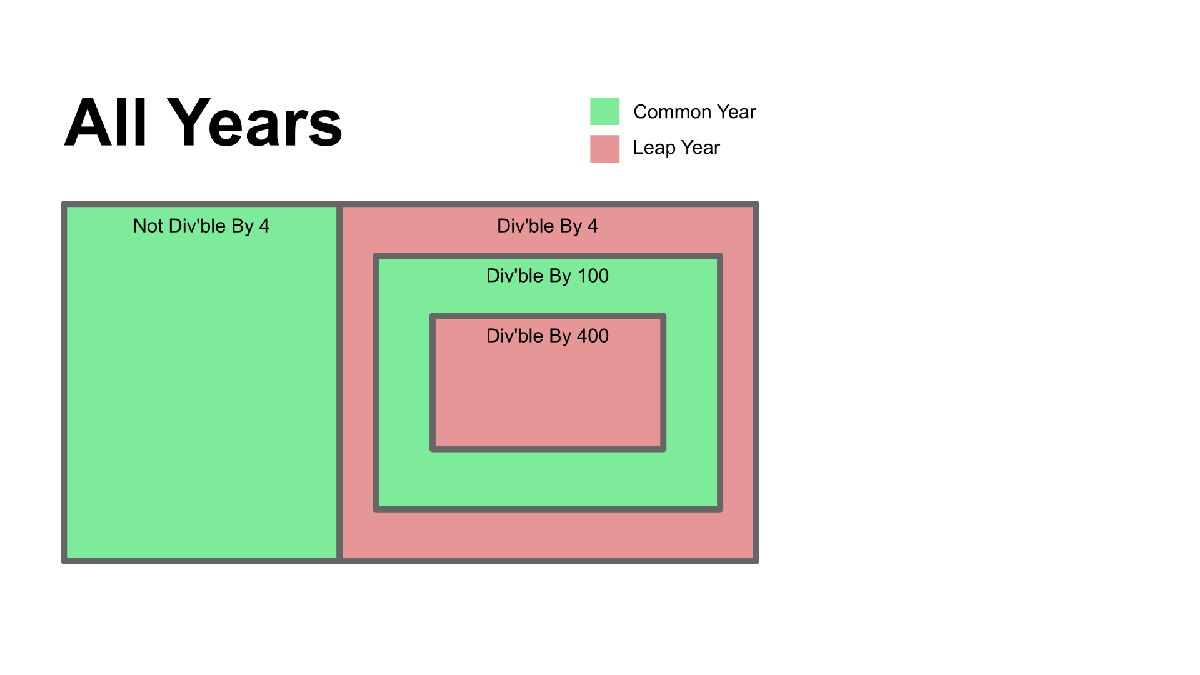

#### Solution 2

Alternately, we can utilize the alternate description of leap years given in the homework prompt, that is,

    *"In simpler terms, a non-century year is a leap year if it is divisible by 4; a century year is a leap year if it is divisible by 400."*

and write

year = 2021;
if mod(year, 100) ~= 0                  % non-century year
    if mod(year, 4) == 0                % rule for leap year
        disp(msgLeap)
    else
        disp(msgCommon)
    end
else                                    % century year
    if mod(year, 400) == 0              % rule for leap year
        disp(msgLeap)
    else
        disp(msgCommon)
    end
end

Given year is a common year.


In words, this is an example in which different rules are used for century years and non-century years.

#### Solution 3

You could piece together multiple conditions characterizing leap years using logical operators.

year = 2021;
if mod(year,4)~=0 || ( mod(year,100)==0 && mod(year,400)~=0 )
    disp(msgCommon)
else
    disp(msgLeap)
end

Given year is a common year.


## Problem 2 (Coordinate Converter)

Given the relationship between the sets of coordinates, one can derive (or recall from calculus) that


$$\begin{array}{rcl}
\rho & = & \sqrt{x^2 + y^2 + z^2} \\
\tan \theta & = & \frac{y}{x} \\
\cos \phi & = & \frac{z}{\sqrt{x^2 + y^2 + z^2}
\end{array}$$


Note that the last equation, when inverted, yields

$\phi = \arccos \frac{z}{\sqrt{x^2 + y^2 + z^2}} = \arccos \frac{z}{\rho}$,

and since the range of $\arccos$ is precisely $[0, \pi]$, it can be easily coded using the built-in `acos` function. However, since we are require to find $\theta \in [0, 2\pi)$, adjustments are called for. Below is the breakdown of possible scenarios according to the quadrants to which $(x,y)$ belongs. Suppose for now that not both $x$ and $y$ are zero.

- [Q1] If $x \ge 0$ and $y \ge 0$, then $\theta = \arctan(y/x)$.

- [Q2] If $x<0$ and $y>0$, then $\theta = \arctan(y/x) + \pi$.

- [Q3] If $x < 0$ and $y \le 0$, then $\theta = \arctan(y/x) + \pi$.

- [Q4] If $x \ge 0$ and $y < 0$, then $\theta = \arctan(y/x) + 2\pi$.

In the edge case of $x = y = 0$, that is, if the point $(x,y,z)$ lies on the $z$-axis:

- $\rho = \sqrt{x^2 + y^2 + z^2} = \vert z \vert$;

- $\phi = 0$ or $\pi$ depending on the sign of $z$;

- $\theta$ can be any number.

We will handle this special case by printing out a separate message.

Let's code it up.

x = -1; y = 0; z = 1;
% x = input('Enter x: ');
% y = input('Enter y: ');
% z = input('Enter z: ');
rho = sqrt(x^2 + y^2 + z^2);
phi = acos(z/rho);
if x < 0
    theta = atan(y/x) + pi;
else
    if y >= 0
        theta = atan(y/x);
    else
        theta = atan(y/x) + 2*pi;
    end
end
disp(' ')

fprintf('rho:    %10.4f\n', rho)

rho:        1.4142


fprintf('phi:    %10.4f\n', phi)

phi:        0.7854


if x == 0 && y == 0
    fprintf('The point is on the z-axis and theta can take any value.')
else
    fprintf('theta:  %10.4f\n', theta)
end

theta:      3.1416


## Problem 3 (LM 5.4--1)

(b) As instructed in the note to the problem, you need not put anything inside the loop. Besides, this is where "*Code Example*" environment comes in handy. 

**Instructors' rant.** Each semester, I always find some students who make their response runnable and prints out all thousand lines in the exported pdf. Please don't.

(d) In the lecture on the conditional statements, we briefly encounter a family of functions whose names begin with `is*`. One of them was `isprime:`

isprime(3)

ans = logical
   1

isprime(4)

ans = logical
   0

We can use it in conjunction with `find` to list prime numbers within a given range. For example, we can find all primes that are $\le 100$ in one statement by

find(isprime(1:100))

ans =      2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97


A slightly more verbose version is

find(isprime(1:100)==1)

ans =      2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97


Therefore, we can write

**Answer.**

**Question.** How would you modify this code so that you execute a `for` loop where the loop index $j$ is 1 through 1000, but not including prime numbers?

**Note 1.** Finding all primes between two arbitrary integers requires more than one line, but not more than two. For example, to find all prime numbers between 10 and 20:

n = 10:20;
n( find(isprime(n)) )

ans =     11    13    17    19


The inner expression `find(isprime(n))` yields the indices of elements of `n `that are prime numbers. We feed it back to `n` to extract them. Even though it works without an issue, MATLAB highlights and underlines "find", suggesting that we use logical indexing in lieu of FIND for potential improvement of performance. Following the suggestion, we can trim it off to

n = 10:20;
n( isprime(n) )

ans =     11    13    17    19


**Note 2.** MATLAB has a handy function that prints out all prime numbers no greater than a given number; it is called `primes.` 

primes(10)

ans =      2     3     5     7


Thus we can write down the answer even more succintly as

(f) Recall the syntax of `for` loop:

So something like the following would do:

(h)

(j)

## Problem 4 (Game of 3-Stick)

We can use `rand` to simulate picking three sticks with random lengths between 0 and 1.

For this triple to be sides of a triangle, the length of **any** one must not exceed the sum of the other two, that is, all of the following must be true:

- `a < b + c`

- `b < a + c`

- `c < a + b`

Let's simulate a single game.

a = rand();
b = rand();
c = rand();
if (a<b+c) && (b<a+c) && (c<a+b)
    disp('You won!')
else
    disp('You lost.')
end

You lost.


To simulate multiple games, you will embed the code above within a `for`-loop. In addition, we will keep track of the number of games won rather than displaying win/loss messages.

nrWins = 0;
nrGames = 20;
for j = 1:nrGames
    a = rand(); b = rand(); c = rand();
    if (a<b+c) && (b<a+c) && (c<a+b)
        nrWins = nrWins + 1;
    end
end
nrWins

nrWins =     14

nrGames

nrGames =     20

Note the deletion of the else-block since we need not do anything in this context. 

**Final Version. **Now that we know that the script above works with a modest number of games, let's increase it to one million as requested by the problem. In addition, let's format outputs nicely using `fprintf` or `disp`.

nrWins = 0;
nrGames = 1e6;   % one million games
for j = 1:nrGames
    a = rand();
    b = rand();
    c = rand();
    if (a<b+c) && (b<a+c) && (c<a+b)
        nrWins = nrWins + 1;
    end
end
pWin = nrWins/nrGames; % prob. of winning a game
fprintf('Games won:     %8d\n', nrWins)

Games won:       499668


fprintf('Games played:  %8d\n', nrGames)

Games played:   1000000


fprintf('Winning ratio: %8.4f\n', pWin)

Winning ratio:   0.4997


**Version Using Arrays.**

The problem was assigned when we did not know about arrays. Now that we do and since Exam 1 is fast approaching, let's try to work this out using arrays. 

**Step 1.** Simulate multiple games using `rand` function.

format short
nrGames = 20;
sticks = rand(3, nrGames)

sticks =     0.0498    0.6049    0.8851    0.5674    0.8530    0.0030    0.9439    0.5081    0.3816    0.8283    0.1192    0.9964    0.4021    0.1306    0.2666    0.6517    0.2466    0.7278    0.8819    0.6036
    0.7871    0.4683    0.8552    0.5402    0.9213    0.8968    0.1868    0.0141    0.2613    0.1951    0.3456    0.5401    0.5571    0.6045    0.3332    0.6595    0.0363    0.8291    0.9955    0.7781
    0.1397    0.6207    0.8558    0.6149    0.8929    0.9925    0.7861    0.6315    0.5048    0.8498    0.1740    0.8609    0.2873    0.8367    0.7032    0.9290    0.8614    0.5191    0.0079    0.9239


Each column corresponds to a single game. The matrix `sticks` holds contains 5 games.

**Step 2.** Generate an auxiliary matrix incorporating the "triangle" conditions. 

I will create an auxiliary matrix `A` (for analysis) whose $j$th columns contain the following information:

- `A(1,j) = -sticks(1,j) + sticks(2,j) + sticks(3,j)`

- `A(2,j) =  sticks(1,j) - sticks(2,j) + sticks(3,j)`

- `A(3,j) =  sticks(1,j) + sticks(2,j) - sticks(3,j)`

In this setup, the $j$th game is won if and only if all entries of the $j$th column of `A` are positive. 

A = zeros(size(sticks));
A(1,:) = -sticks(1,:) + sticks(2,:) + sticks(3,:);
A(2,:) =  sticks(1,:) - sticks(2,:) + sticks(3,:);
A(3,:) =  sticks(1,:) + sticks(2,:) - sticks(3,:);
A

A =     0.8770    0.4841    0.8260    0.5876    0.9611    1.8863    0.0290    0.1375    0.3846    0.2166    0.4004    0.4046    0.4423    1.3106    0.7698    0.9369    0.6512    0.6205    0.1215    1.0983
   -0.5976    0.7573    0.8857    0.6421    0.8246    0.0988    1.5431    1.1255    0.6251    1.4830   -0.0524    1.3172    0.1323    0.3627    0.6366    0.9212    1.0716    0.4178   -0.1057    0.7494
    0.6973    0.4526    0.8844    0.4928    0.8815   -0.0927    0.3447   -0.1093    0.1381    0.1736    0.2908    0.6757    0.6719   -0.1015   -0.1034    0.3821   -0.5785    1.0378    1.8695    0.4578


**    Sidenote. **The matrix `A` can be constructed by a single statement

    This is a triumphant moment in which the understanding of matrix multiplication shines in progamming! (Make sure you understand why this works!)

Now, I will replace positive entries of `A` by 1 and non-positive (that is, less than or equal to zero) entries by 0.

A( find(A >0) ) = 1;
A( find(A<=0) ) = 0;
A

A =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     0     1
     1     1     1     1     1     0     1     0     1     1     1     1     1     0     0     1     0     1     1     1


**Step 3.** Identify the games won.

Finally, generate a row vector by sum all elements of `A` along columns:

sumA = sum(A)

sumA =      2     3     3     3     3     2     3     2     3     3     2     3     3     2     2     3     2     3     2     3


The elements that are equal to 3 correspond to the games won!

**Full script (Vectorized).**

Let's put all together.

nrGames = 1e6;
sticks = rand(3, nrGames);
A = [-1 1 1; 1 -1 1; 1 1 -1] * sticks;
A( find(A >0) ) = 1;
A( find(A<=0) ) = 0;
sumA = sum(A);
nrWins = length(find(sumA==3));
pWin = nrWins/nrGames; % prob. of winning a game
fprintf('Games won:     %8d\n', nrWins)

Games won:       499802


fprintf('Games played:  %8d\n', nrGames)

Games played:   1000000


fprintf('Winning ratio: %8.4f\n', pWin)

Winning ratio:   0.4998


## Problem 5 (Convergence of Sequences)

We will take the value of `pi` stored in MATLAB as the true value of $\pi$. As a prep work, suppose that `n` is given. We will concentrate first on calculating $a_n$ and $b_n$. Using a `for`-loop, we can form these terms as below:

format long g
n = 10;
a_n = 0; b_n = 0;
for k = 0:n
    a_n = a_n + 6/sqrt(3)*(-1/3)^k / (2*k+1);
    b_n = b_n + 16/5*(-1/25)^k / (2*k+1) - 4/239*(-1/239^2)^k / (2*k+1);
end
a_n

a_n =           3.14159330450308

b_n

b_n =           3.14159265358979

As the last lines show, with only $n = 10$, they are already quite close to $\pi$. 

Now that the key part of the problem has been solve, let's design an outer loop which calculates terms $a_0, a_1, \ldots$ until it is close enough to $\pi$; the given *tolerance* is $10^{-6}$. 

tol = 1e-6;
nMax = 100;    % maximum number of iterations
n = 0;
% fprintf('%2s %16s %16s\n', 'n', 'a_n', '|a_n - pi|');
% fprintf('%36s', repmat('-', 1, 36))
while n == 0 || (errAbs > tol && n <= nMax)
    a = 0;
    for k = 0:n
        a = a + (-1/3)^k / (2*k+1);
    end
    a = 6/sqrt(3)*a;   % since 6/sqrt(3) is a common factor.
    errAbs = abs(a - pi);
    fprintf('%2d %16.8f %16.8e\n', n, a, errAbs)
    n = n + 1;
end

 0       3.46410162   3.22508962e-01
 1       3.07920144   6.23912179e-02
 2       3.15618147   1.45888180e-02
 3       3.13785289   3.73976199e-03
 4       3.14260475   1.01209207e-03
 5       3.14130879   2.83868127e-04
 6       3.14167431   8.16591090e-05
 7       3.14156872   2.39376480e-05
 8       3.14159977   7.12022171e-06
 9       3.14159051   2.14265171e-06
10       3.14159330   6.50913289e-07


**Note.** Before the beginning of the `while`-loop, the variable `errAbs` was not initialized and so the loop would not be initated if it were not for `n==0` preceding `(errAbs ... )`. An alternate method that is commonly used is to begin with

You handle $b_n$'s in the same fashion.

tol = 1e-6;
nMax = 100;    % maximum number of iterations
n = 0;
% fprintf('%2s %16s %16s\n', 'n', 'b_n', '|b_n - pi|');
% fprintf('%36s', repmat('-', 1, 36))
while n == 0 || (errAbs > tol && n <= nMax)
    b1 = 0; b2 = 0;
    for k = 0:n
        b1 = b1 + (-1/25)^k/(2*k+1);
        b2 = b2 + (-1/239^2)^k/(2*k+1);
    end
    b = 16/5*b1 - 4/239*b2;
    errAbs = abs(b - pi);
    fprintf('%2d %16.8f %16.8e\n', n, b, errAbs)
    n = n + 1;
end

 0       3.18326360   4.16709447e-02
 1       3.14059703   9.95624264e-04
 2       3.14162103   2.83757352e-05
 3       3.14159177   8.81407615e-07


The two numerical experiments provide an evidence that the sequence $b_n$ may converge to $\pi$ much quicker than $a_n$. 